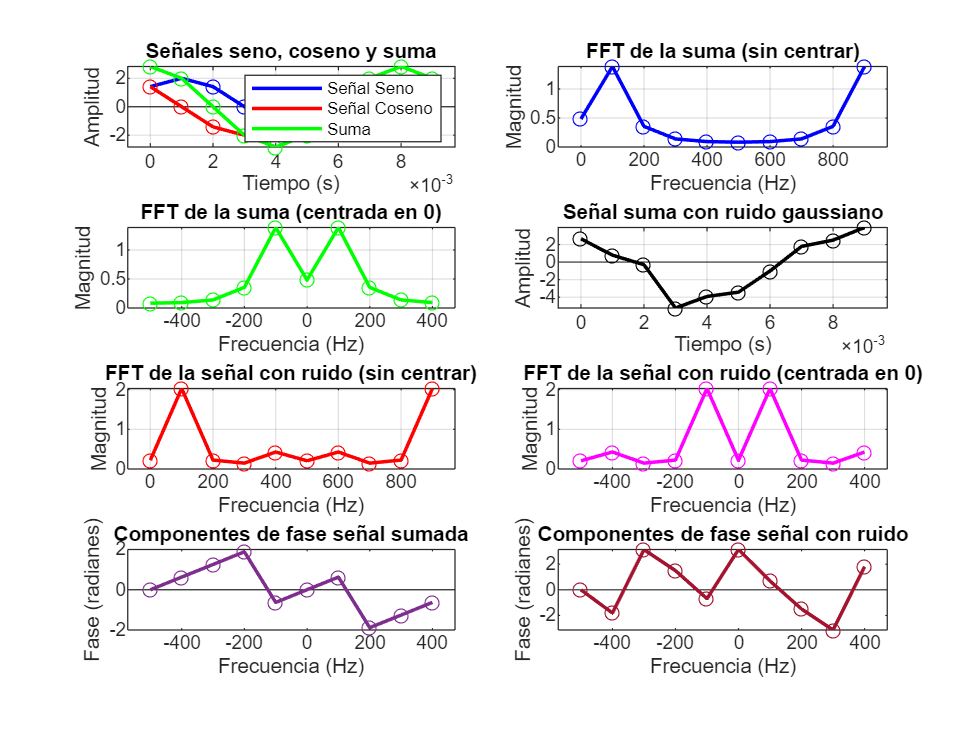

clc;
clear;

% Parámetros de las señales
A = 2; % Amplitud de las señales
f = 125; % Frecuencia de las señales (Hz)
des_sin = deg2rad(45); % Desfase de la señal seno
des_cos = deg2rad(45); % Desfase de la señal coseno

% Parámetros de muestreo
fs = 1000; % Frecuencia de muestreo (Hz)
tiempo = 10; % Tiempo total de grabación (milisegundos)

% Tiempo continuo y muestreo
T = tiempo / 1000; % Convertir tiempo a segundos
Ts = 1 / fs; % Periodo de muestreo
t = 0:Ts:T-Ts; % Vector de tiempo discreto (muestreo)

% Generar y sumar señales seno y coseno
[x_sin, x_cos, x_sum] = generar_senales(A, f, t, des_sin, des_cos);

% FFT de la suma sin centrar
[X_fft, freqs] = aplicar_fft(x_sum, fs, length(t));

% FFT de la suma centrada en 0
[X_fftCentral, freqsCentral] = aplicar_fft_centrada(x_sum, fs, length(t));

%%% Magnitud señal sumada
magnitud = obtenerMagnitud(X_fftCentral);

%%% Componentes de fase señal sumada
fase = obtenerFase(X_fftCentral);

% Aplicar ruido gaussiano a la señal de la suma
x_sumRuido = aplicar_ruido(x_sum);

% FFT de la señal con ruido sin centrar
[X_fftRuido, ~] = aplicar_fft(x_sumRuido, fs, length(t));

% FFT de la señal con ruido centrada en 0
[X_fftRuidoCentral, ~] = aplicar_fft_centrada(x_sumRuido, fs, length(t));

%%% Magnitud señal con ruido
magnitudR = obtenerMagnitud(X_fftRuidoCentral);

%%% Fase de señal con ruido
faseR = obtenerFase(X_fftRuidoCentral);

% Graficar resultados
graficar_resultados(t, x_sin, x_cos, x_sum, x_sumRuido, freqs, X_fft, X_fftCentral, freqsCentral, X_fftRuido, X_fftRuidoCentral, fase, faseR, magnitud, magnitudR);


%Función para generar las señales seno, coseno y la suma
function [x_sin, x_cos, x_sum] = generar_senales(A, f, t, des_sin, des_cos)
    x_sin = A * sin(2 * pi * f * t + des_sin);
    x_cos = A * cos(2 * pi * f * t + des_cos);
    x_sum = x_sin + x_cos; % Suma de las señales
end

%Función para aplicar la FFT
function [X_fft, freqs] = aplicar_fft(x, fs, N)
    X_fft = fft(x); % FFT de la señal
    freqs = (0:N-1)*(fs/N); % Frecuencias correspondientes
end

%Función para aplicar la FFT centrada en 0
function [X_fft_centrada, freqs_central] = aplicar_fft_centrada(x, fs, N)
    X_fft_centrada = fftshift(fft(x)); % FFT de la señal centrada en 0
    freqs_central = (-N/2:N/2-1)*(fs/N); % Frecuencias centradas en 0
end

%Función para aplicar ruido gaussiano a la señal
function xRuido = aplicar_ruido(x)
    ruidoGauss = randn(size(x)); % Generar ruido gaussiano
    xRuido = x + ruidoGauss; % Señal con ruido
end

%Obtener la magnitud de la señal
function magnitud = obtenerMagnitud(X_fft_centrada)
    magnitud = abs(X_fft_centrada); %Componentes de fase
end

%Obtener los componentes de fase
function fase = obtenerFase(X_fft_centrada)
    fase = angle(X_fft_centrada); %Componentes de fase
end

%Función para graficar resultados
function graficar_resultados(t, x_sin, x_cos, x_sum, x_sum_ruido, freqs, X_fft, X_fft_shifted, freqsCentral, X_fft_ruido, X_fft_ruido_shifted, fase, faseR, magnitud, magnitudR)
    figure;

    % Señales originales y suma
    subplot(4,2,1);
    plot(t, x_sin, 'b', 'LineWidth', 1.5);
    hold on;
    plot(t, x_cos, 'r', 'LineWidth', 1.5);
    plot(t, x_sum, 'g', 'LineWidth', 1.5);
    stem(t, x_sin, 'b', 'Marker', 'o', 'LineStyle', 'none');
    stem(t, x_cos, 'r', 'Marker', 'o', 'LineStyle', 'none');
    stem(t, x_sum, 'g', 'Marker', 'o', 'LineStyle', 'none');
    title('Señales seno, coseno y suma');
    xlabel('Tiempo (s)');
    ylabel('Amplitud');
    legend('Señal Seno', 'Señal Coseno', 'Suma');
    grid on;

    % FFT de la suma sin centrar
    subplot(4,2,2);
    plot(freqs, abs(X_fft) / length(t), 'b', 'LineWidth', 1.5);
    hold on;
    stem(freqs, abs(X_fft) / length(t), 'b', 'Marker', 'o', 'LineStyle', 'none');
    title('FFT de la suma (sin centrar)');
    xlabel('Frecuencia (Hz)');
    ylabel('Magnitud');
    grid on;

    % FFT de la suma centrada en 0
    subplot(4,2,3);
    plot(freqsCentral, abs(X_fft_shifted) / length(t), 'g', 'LineWidth', 1.5);
    hold on;
    stem(freqsCentral, abs(X_fft_shifted) / length(t), 'g', 'Marker', 'o', 'LineStyle', 'none');
    title('FFT de la suma (centrada en 0)');
    xlabel('Frecuencia (Hz)');
    ylabel('Magnitud');
    grid on;

    % Señal suma con ruido gaussiano
    subplot(4,2,4);
    plot(t, x_sum_ruido, 'k', 'LineWidth', 1.5);
    hold on;
    stem(t, x_sum_ruido, 'k', 'Marker', 'o', 'LineStyle', 'none');
    title('Señal suma con ruido gaussiano');
    xlabel('Tiempo (s)');
    ylabel('Amplitud');
    grid on;

    % FFT de la señal con ruido sin centrar
    subplot(4,2,5);
    plot(freqs, abs(X_fft_ruido) / length(t), 'r', 'LineWidth', 1.5);
    hold on;
    stem(freqs, abs(X_fft_ruido) / length(t), 'r', 'Marker', 'o', 'LineStyle', 'none');
    title('FFT de la señal con ruido (sin centrar)');
    xlabel('Frecuencia (Hz)');
    ylabel('Magnitud');
    grid on;

    % FFT de la señal con ruido centrada en 0
    subplot(4,2,6);
    plot(freqsCentral, abs(X_fft_ruido_shifted) / length(t), 'm', 'LineWidth', 1.5);
    hold on;
    stem(freqsCentral, abs(X_fft_ruido_shifted) / length(t), 'm', 'Marker', 'o', 'LineStyle', 'none');
    title('FFT de la señal con ruido (centrada en 0)');
    xlabel('Frecuencia (Hz)');
    ylabel('Magnitud');
    grid on;

    % Componentes de fase señal sumada
    subplot(4,2,7);
    plot(freqsCentral, fase, 'Color', '#7E2F8E', 'LineWidth', 1.5);
    hold on;
    stem(freqsCentral, fase, 'Color', '#7E2F8E', 'Marker', 'o', 'LineStyle', 'none');
    title('Componentes de fase señal sumada');
    xlabel('Frecuencia (Hz)');
    ylabel('Fase (radianes)');

    % Componentes de fase señal con ruido
    subplot(4,2,8);
    plot(freqsCentral, faseR, 'Color', '#A2142F', 'LineWidth', 1.5);
    hold on;
    stem(freqsCentral, faseR, 'Color', '#A2142F', 'Marker', 'o', 'LineStyle', 'none');
    title('Componentes de fase señal con ruido');
    xlabel('Frecuencia (Hz)');
    ylabel('Fase (radianes)');
end
